# 第4章: 形態素解析

Copyright (c) 2020 NLP100-MATLAB

夏目漱石の小説『吾輩は猫である』の文章（[neko.txt](https://nlp100.github.io/data/neko.txt)）をMeCabを使って形態素解析し，その結果をneko.txt.mecabというファイルに保存せよ．このファイルを用いて，以下の問に対応するプログラムを実装せよ．

なお，問題37, 38, 39は[matplotlib](http://matplotlib.org/)もしくは[Gnuplot](http://www.gnuplot.info/)を用いるとよい．

## 環境

MATLABR2020a 

TextAnalyticsToolbox

## 準備

形態素解析はMATLAB上でできてしまうので，あえてMeCabをスタンドアロンで使う必要はないのですが，どうしてもお題の通りにやろうとすると次のようになります（MeCabはインストール済とします）．ただし，Windows上で普通にインストールしたMeCabだと，UTF-8のファイルの処理はできないので，テキストファイルのエンコーディングをShift-JISに変換してから行うことになります．

mecabCommand = '"C:\Program Files (x86)\MeCab\bin\mecab.exe"';
inputFile = 'nekoSJIS.txt';
outputFile = 'neko.txt.mecab';

system(sprintf('%s %s -o %s',mecabCommand,inputFile,outputFile));

## 30. 形態素解析結果の読み込み

形態素解析結果（neko.txt.mecab）を読み込むプログラムを実装せよ．ただし，各形態素は表層形（surface），基本形（base），品詞（pos），品詞細分類1（pos1）をキーとするマッピング型に格納し，1文を形態素（マッピング型）のリストとして表現せよ．第4章の残りの問題では，ここで作ったプログラムを活用せよ．

せっかくText Analytics Toolboxがあるので，MeCabの出力を読み込むことはせずに，直接MATLAB上で処理をします．「各形態素をマッピング型に格納し，1文を形態素（マッピング型）のリストとして表現せよ」というところは，`tokenizedDocument `オブジェクトが対応する「マッピング型」である（表層系などの詳細情報は直接参照できないけど）と強弁してやり過ごすことにします．ただし，MeCabの品詞再分類の情報が必要なので，ちょっと工夫がいります．詳しくは こちらの記事をどうぞ．

まず，ファイルを全部読み込んでから1行ごとに分割します．その結果を形態素解析にかけますが，このときに一工夫してMeCabの詳細出力を取得するようにします．

str = fileread("neko.txt");
str = splitlines(str);

mecabOpt = mecabOptions("LemmaExtractor",@(~,info) info.Feature); % MeCabの詳細出力をとるための一工夫

docs = tokenizedDocument(str,'TokenizeMethod',mecabOpt); % 形態素解析

トークンの詳細表を作成します．

tknsOrg = tokenDetails(docs);

head(tknsOrg)

ans = 8×8 table
    Token     DocumentNumber    LineNumber       Type        Language     PartOfSpeech                        Lemma                          Entity  
    ______    ______________    __________    ___________    ________    ______________    ____________________________________________    __________

    "一"            1               1         letters           ja       numeral           "名詞,数,*,*,*,*,一,イチ,イチ"                     non-entity
    "吾輩"          3               1         letters           ja       pronoun           "名詞,代名詞,一般,*,*,*,吾輩,ワガハイ,ワガハイ"        non-entity
    "は"            3               1         letters           ja       adposition        "助詞,係助詞,*,*,*,*,は,ハ,ワ"                     non-entity
    "猫"            3               1         letters           ja       noun              "名詞,一般,*,*,*,*,猫,ネコ,ネコ"                   non-entity
    "で"            3               1         letters           ja       auxiliary-verb    "助動詞,*,*,*,特殊・ダ,連用形,だ,デ,

`tkns.Lemma `の所に，MeCabの生出力が出てます．そこで，ここの情報を使ってトークン表を少し書き換えます．

まず，MeCabの品詞分類情報（`tkns.Lemma`）の最大項目数，トークン表の行数を取得し，品詞情報を格納する配列 `posArray` を用意します．

nPos  = 9;                        % MeCabの品詞分類出力の列数（固定値）
nDocs = height(tknsOrg);             % トークン表の行数
posArray = repmat("",nDocs,nPos); % 品詞情報を格納する配列を用意します．

次に，`tkns.Lemma` を1行ずつ分割して posArray を埋めてゆきます．

for kk = 1:nDocs
  [splitPOS,nPOS] = split(tknsOrg.Lemma(kk),',');
  posArray(kk,1:numel(nPOS)+1) = splitPOS;
end

 現在のトークン表をコピーして出力トークン表を作成し，posArray の内容を加えてゆきます．

tkns = tknsOrg(:,{'DocumentNumber','LineNumber'});
tkns.surface  = tknsOrg.Token; 
tkns.base     = posArray(:,7);
tkns.POS      = categorical(posArray(:,1));
tkns.POS1     = categorical(posArray(:,2));

head(tkns)

ans = 8×6 table
    DocumentNumber    LineNumber    surface     base      POS     POS1 
    ______________    __________    _______    ______    _____    _____

          1               1         "一"       "一"      名詞      数   
          3               1         "吾輩"     "吾輩"     名詞      代名詞
          3               1         "は"       "は"      助詞      係助詞
          3               1         "猫"       "猫"      名詞      一般  
          3               1         "で"       "だ"      助動詞    *    
          3               1         "ある"     "ある"     助動詞    *    
          3               1         "。"       "。"      記号      句点  
          4               1         "名前"     "名前"     名詞      一般  


できましたね．最初の横棒”ー”が名詞・数に分類されているのがなんだかなぁ．

## 31. 動詞

動詞の表層形をすべて抽出せよ．

これは簡単．`tkns` がテーブル形で，`tkns.POS` 等が`categorical` 配列になっているので，抽出が簡単にできます．

verbs = tkns.surface(tkns.POS=="動詞")

verbs = 28907×1 の string 配列
    "生れ"
    "つか"
    "し"
    "泣い"
    "し"
    "いる"
    "始め"
    "見"
    "聞く"
    "捕え"
    "煮"
    "食う"
    "思わ"
    "載せ"
    "られ"
    "持ち上げ"
    "られ"
    "し"
    "あっ"
    "落ちつい"
    "見"
    "見"
    "思っ"
    "残っ"
    "いる"
    "さ"
    "れ"
    "し"
    "逢っ"
    "出会わ"


## 32. 動詞の原形

動詞の原形をすべて抽出せよ．

これも一発

verbsBase = tkns.base(tkns.POS=="動詞")

verbsBase = 28907×1 の string 配列
    "生れる"
    "つく"
    "する"
    "泣く"
    "する"
    "いる"
    "始める"
    "見る"
    "聞く"
    "捕える"
    "煮る"
    "食う"
    "思う"
    "載せる"
    "られる"
    "持ち上げる"
    "られる"
    "する"
    "ある"
    "落ちつく"
    "見る"
    "見る"
    "思う"
    "残る"
    "いる"
    "する"
    "れる"
    "する"
    "逢う"
    "出会う"


## 33. 「AのB」

2つの名詞が「の」で連結されている名詞句を抽出せよ．

３つの単語の並びなので，トライグラムかなぁなどと思ってみたのですが，もう少し簡単なやり方を発見しました．まず，表層形が「の」であるトークンのインデックス（論理配列 `lidxA`とします）と，品詞が「名詞」であるトークンのインデックス（論理配列 `lidxB`とします）を取得します．

lidxA = strcmp("の",tkns.surface); % 論理配列A
lidxB = tkns.POS=="名詞";          % 論理配列B

次に，これらの論理配列を１要素ずつずらしながら論理積（`and`）をとります．

lidx = lidxB(1:end-2) & lidxA(2:end-1) & lidxB(3:end);

こうして出来上がった論理配列は，true の要素が「名詞－の－名詞」の並びの最初のTokenに対応する論理配列となります．

idx = find(lidx);

表層形の一覧から，得られた論理配列に対応するトークンとそれに続く２つのトークンを抽出し連結すればできあがり．


nounPhrase = tkns.surface(idx)+tkns.surface(idx+1)+tkns.surface(idx+2)

nounPhrase = 6040×1 の string 配列
    "彼の掌"
    "掌の上"
    "書生の顔"
    "はずの顔"
    "顔の真中"
    "穴の中"
    "書生の掌"
    "掌の裏"
    "何の事"
    "肝心の母親"
    "藁の上"
    "笹原の中"
    "池の前"
    "池の上"
    "一樹の蔭"
    "垣根の穴"
    "隣家の三"
    "時の通路"
    "一刻の猶予"
    "家の内"
    "彼の書生"
    "以外の人間"
    "前の書生"
    "おさんの隙"
    "おさんの三"
    "胸の痞"
    "家の主人"
    "主人の方"
    "鼻の下"
    "吾輩の顔"


## 34. 名詞の連接

名詞の連接（連続して出現する名詞）を最長一致で抽出せよ．

基本は名詞の抽出から．直接文字列を扱うのも何なので，論理配列で話を進めましょう．

lidx = tkns.POS=="名詞";

連続して出現しているということは，単独ではないということ．単独である条件は，両側が名詞ではないこと．ですので，単独で出現する名詞に対応する論理配列は次のようになります．なお，`lidx`の最初と最後の要素の隣に，`false`を加えて端点処理を行っています．

lidxIso = (~[false; lidx(1:end-1)]&~[lidx(2:end);false]);

なので，資格のある名詞は

lidx = lidx & ~lidxIso;

資格のない言葉を全て空白で置き換えて，全体を一つの文字列にしてから，正規表現で抽出というのはどうでしょう．

strContNoun = tkns.surface;
strContNoun(~lidx)= ' ';
strContNoun = char(join(strContNoun,''));

contNoun = string(regexp(strContNoun,'[^\s]+','match'))'

contNoun = 7188×1 の string 配列
    "一吾輩"
    "人間中"
    "一番獰悪"
    "時妙"
    "一毛"
    "その後猫"
    "一度"
    "ぷうぷうと煙"
    "邸内"
    "三毛"
    "書生以外"
    "四五遍"
    "この間おさん"
    "三馬"
    "御台所"
    "まま奥"
    "住家"
    "終日書斎"
    "勉強家"
    "勉強家"
    "勤勉家"
    "二三ページ"
    "主人以外"
    "限り吾輩"
    "朝主人"
    "一番心持"
    "二人"
    "一つ床"
    "一人"
    "最後大変"


もう少しエレガントなやり方もありそうなものですが・・・

## 35. 単語の出現頻度

文章中に出現する単語とその出現頻度を求め，出現頻度の高い順に並べよ．

これは，Bag-of-words モデルそのものですね．

bow = bagOfWords(docs)

bow =   bagOfWords のプロパティ:

          Counts: [9965×13580 double]
      Vocabulary: [1×13580 string]
        NumWords: 13580
    NumDocuments: 9965


関数 topkwords で，頻出K単語の降順テーブルを作ってくれます．全ての単語の出現頻度を知りたければ，引数Kに，全単語数を入れればOK．

bowTable = topkwords(bow,bow.NumWords)

bowTable = 13580×2 table
     Word     Count
    ______    _____

    "の"      9194 
    "。"      7486 
    "て"      6868 
    "、"      6772 
    "は"      6420 
    "に"      6243 
    "を"      6071 
    "と"      5508 
    "が"      5337 
    "た"      3988 
    "で"      3806 
    "「"      3231 
    "」"      3225 
    "も"      2479 
    "ない"    2390 
    "だ"      2363 


前処理をしないと，「てにほは」ばっかりが頻出する面白くない結果になってしまいますね．そこで，あまり面白くない単語を除去する関数 removeStopWords と，句読点などの記号を除去する関数 `erasePunctuation` を使ってから bag-of-words モデルを作成してみましょう．

docs = removeStopWords(docs);
docs = erasePunctuation(docs);
bow = bagOfWords(docs)

bow =   bagOfWords のプロパティ:

          Counts: [9965×13236 double]
      Vocabulary: [1×13236 string]
        NumWords: 13236
    NumDocuments: 9965


bowTable = topkwords(bow,bow.NumWords)

bowTable = 13236×2 table
     Word     Count
    ______    _____

    "君"       973 
    "云う"     937 
    "主人"     932 
    "御"       636 
    "ば"       617 
    "なら"     483 
    "吾輩"     481 
    "じゃ"     448 
    "なっ"     404 
    "来"       364 
    "れ"       356 
    "迷亭"     343 
    "いい"     320 
    "寒月"     286 
    "顔"       282 
    "ぬ"       277 


## 36. 頻度上位10語

出現頻度が高い10語とその出現頻度をグラフ（例えば棒グラフなど）で表示せよ．

ここは素直にそのまま．問題35で求めた`bowTable` を使います．

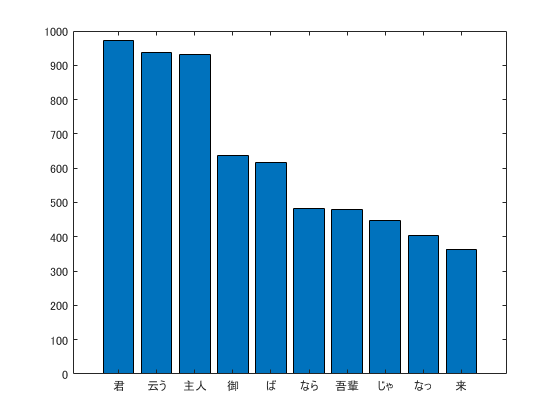

bar(bowTable.Count(1:10));
set(gca,'XTickLabel',bowTable.Word(1:10));

## 37. 「猫」と共起頻度の高い上位10語

「猫」とよく共起する（共起頻度が高い）10語とその出現頻度をグラフ（例えば棒グラフなど）で表示せよ．

「共起」を考える際は，コンテクストのスパンを指定する必要があるのですが，ここでは7語（文書の長さのメディアン値+1）にしておきます．まず，文書から「猫」がふくまれるコンテクストを抽出します．

span = 7;
coWords = context(docs,"猫",span)

coWords = 248×3 table
            Context             Document    Word
    ________________________    ________    ____

    "    吾輩 猫       "             3         2 
    "       猫 だいぶ 逢っ"          16         1 
    "宿 なし 小 猫 いくら 出し"       66         9 
    "    吾輩 猫 ながら 時々"         87         2 
    "勤まる なら 猫 出来 ぬ  "        90         5 
    " 質 わるい 猫 来 猫 来 "        104         7 
    "るい 猫 来 猫 来 いっ 夜"       104         9 
    "うしても 我 猫 族 親子 愛"      117         9 
    " まあ 永く 猫 時節 待つ "       128         3 
    "    吾輩 猫 として 決し"        171         2 
    "いい あえて 猫 勝る 決して"      172         9 
    "輩 波 斯産 猫 ごとく 黄 "       175         4 
    "い 見え 盲 猫 寝 猫 判然"       180         9 
    " 盲 猫 寝 猫 判然    "         180        11 
    "倒し 大きな 猫 前後 不覚 "      201        15 
    "  純粋 黒 猫       "          204         3 


コンテキストとして抽出した文 `coWords.Context` は単語が空白で区切られた文字列になっているので，これらの単語を空白で分割して文字列配列に格納します．また，余分な空文字列`""`と，単語`"猫"`を除去します．

wordCat = coWords.Context;
tmp = arrayfun(@(x) split(x,' ')',wordCat,'UniformOutput',false);

tmp = [tmp{:}];                  % セル配列を文字列配列に変換
tmp = tmp( tmp~="" & tmp~="猫");  % 空文字列および"猫"の除去
wordCat = tmp;

統計を取るために，bag-of-words モデルを生成し，頻出上位10語を抽出します．

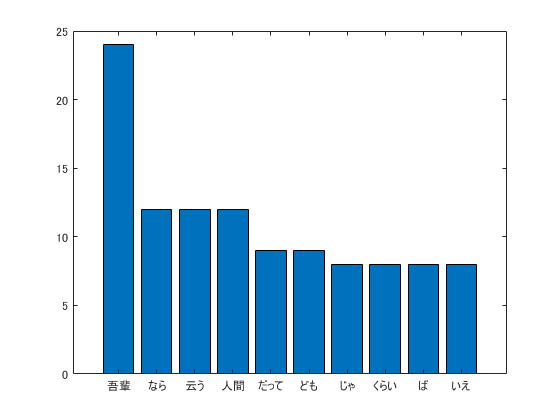

bowCat = bagOfWords(wordCat);

bowCatTable = topkwords(bowCat,10);
bar(bowCatTable.Count);
set(gca,'XTickLabel',bowCatTable.Word);

## 38. ヒストグラム

単語の出現頻度のヒストグラム（横軸に出現頻度，縦軸に出現頻度をとる単語の種類数を棒グラフで表したもの）を描け．

殆どの単語の出現頻度は数回なので，ヒストグラムのビンを出現頻度の低いところに集中させています．出現頻度50回以上の単語数は，一つのビンにまとめて表示させています．

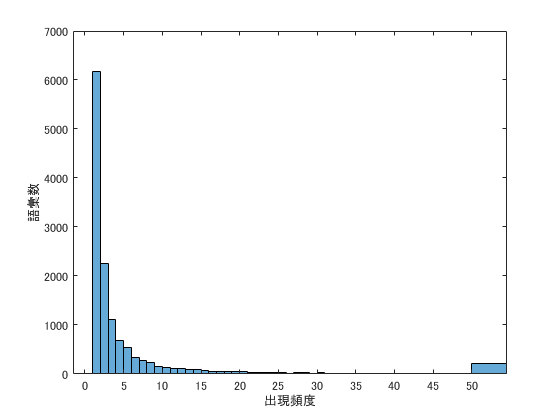

histogram(bowTable.Count,[1:50 Inf]);
xlabel('出現頻度');
ylabel('語彙数');

## 39. Zipfの法則

単語の出現頻度順位を横軸，その出現頻度を縦軸として，両対数グラフをプロットせよ．

これも，出現頻度表 `bowTable` の内容をそのまま両対数プロットすればよいだけですね．厳密に言えば，bowTableの行番号は順位と必ずしも一致しませんが，Zipfの法則を視覚化する目的では順位だと見なしてもほぼ問題ないでしょう．

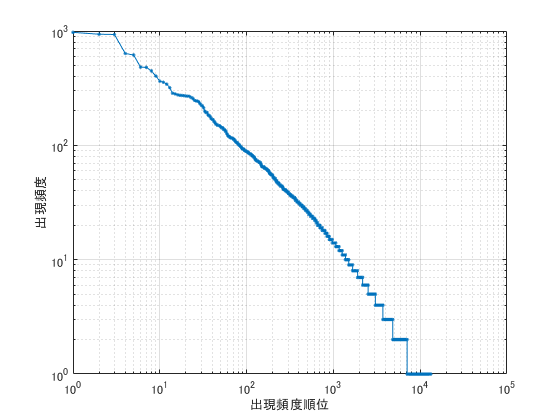

loglog(1:height(bowTable),bowTable.Count,'.-');
grid on;
xlabel('出現頻度順位');
ylabel('出現頻度')